# Panel models with cross sections

Tutorial file for testing panel models

## Housekeeping

clear
close all
clear classes

rehash path


import cross.*  


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

defaultColors = get(0, "defaultAxesColorOrder");

## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information is common to all cross-section panel BVAR models, regardless of the specific estimator used.

The properties are as follows:

**endogenousConcepts **–  a list of endogenous variables, listed without the country suffix. Plays the same role as **endogenousNames** in plain BVARs

**units **– a list of countries/units that share the same endogenous variables


estimStart = datex("1972-Q1");
estimEnd = datex("2014-Q4");
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousConcepts=["YER", "HICSA", "STN"], ...
    units=["US", "EA", "UK"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);



## Specifying and loading input data


inputTbl = tablex.fromFile("panelData.csv");
dataH = DataHolder(meta, inputTbl);

## Reduced form models

There are some common properties for the cross section panel BVARs. Which are

**Alpha0 (1000)** – The shape of the Inverse Gamma distribution of residual variances

**Delta0 (1)** – The scale of the Inverse Gamma distribution of residual variances

#### Static Cross Panel

estimatorR1 = estimator.StaticCrossPanel(meta);

#### Dynamic Cross Panel

**A0 (1000)** – The shape of the Inverse Gamma distribution of factor variances

**B0 (1)** – The scale of the Inverse Gamma distribution of factor variances

**Rho (0.75)** – The AR coefficient in the prior for factor coefficients.

**Gamma (0.85)** – The AR coefficient for latent innovation series

% estimatorR1 = estimator.DynamicCrossPanel(meta);

### Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta, ...
    dataHolder=dataH, ...
    estimator=estimatorR1 ...
);

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.2289
    0.1743
    0.1743
    0.1732
    0.1185
    0.1185
    0.1732
    0.1185
    0.1185
    0.0004


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2012-Q2


fcastEnd = datetime
   2014-Q4



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

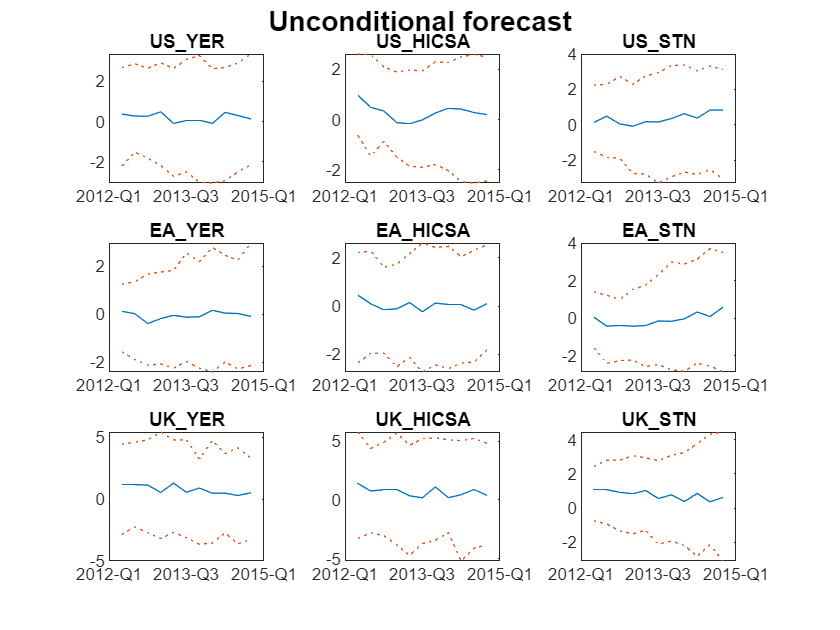


plotSettings = { ...
    {"color"}, {defaultColors(2,:); defaultColors(1,:); defaultColors(2,:)},  ...
    {"lineStyle"}, {":";"-";":"}, ...
};


ch = visual.Chartpack( ...
    span=datex.span(fcastStart, fcastEnd), ...
    namesToPlot=[modelR1.Meta.EndogenousNames], ...
    plotSettings=plotSettings ...
);

ch.Captions = "Unconditional forecast";
ch.plot(fcastPrctileTbx);

## Identification

### Cholesky

#### Seting up the identifier

identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info1 = modelS1.presample(numPresampled);


 Presampling from posterior (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [342×1 double]
                 sigma: [81×1 double]
    IdentificationDraw: [1×1 struct]
                     D: [9×9 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [9×9 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.2256    0.1690    0.1690    0.1674    0.1108    0.1108    0.1674    0.1108    0.1108
    0.1690    0.2331    0.1690    0.1108    0.1749    0.1108    0.1108    0.1749    0.1108
    0.1690    0.1690    0.2433    0.1108    0.1108    0.1851    0.1108    0.1108    0.1851
    0.1674    0.1108    0.1108    0.2248    0.1682    0.1682    0.1674    0.1108    0.1108
    0.1108    0.1749    0.1108    0.1682    0.2323    0.1682    0.1108    0.1749    0.1108
    0.1108    0.1108    0.1851    0.1682    0.1682    0.2425    0.1108    0.1108    0.1851
    0.1674    0.1108    0.1108    0.1674    0.1108    0.1108    0.2327    0.1761    0.1761
    0.1108    0.1749    0.1108    0.1108    0.1749    0.1108    0.1761    0.2402    0.1761
    0.1108    0.1108    0.1851    0.1108    0.1108    0.1851    0.1761    0.1761    0.2504
    0.0139   -0.0427   -0.0427   -0.0443   -0.1009   -0.1009   -0.0443   -0.1009   -0.1009


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.2256    0.1690    0.1690    0.1674    0.1108    0.1108    0.1674    0.1108    0.1108
    0.1690    0.2331    0.1690    0.1108    0.1749    0.1108    0.1108    0.1749    0.1108
    0.1690    0.1690    0.2433    0.1108    0.1108    0.1851    0.1108    0.1108    0.1851
    0.1674    0.1108    0.1108    0.2248    0.1682    0.1682    0.1674    0.1108    0.1108
    0.1108    0.1749    0.1108    0.1682    0.2323    0.1682    0.1108    0.1749    0.1108
    0.1108    0.1108    0.1851    0.1682    0.1682    0.2425    0.1108    0.1108    0.1851
    0.1674    0.1108    0.1108    0.1674    0.1108    0.1108    0.2327    0.1761    0.1761
    0.1108    0.1749    0.1108    0.1108    0.1749    0.1108    0.1761    0.2402    0.1761
    0.1108    0.1108    0.1851    0.1108    0.1108    0.1851    0.1761    0.1761    0.2504
    0.0139   -0.0427   -0.0427   -0.0443   -0.1009   -0.1009   -0.0443   -0.1009   -0.1009


#### Checking scaling matrix

modelS1.Presampled{1}.D

ans =     1.3648   -0.4409   -0.3342    0.3277   -0.2729    0.1848    0.0661   -0.0950   -0.3801
         0    0.8521    0.1655   -0.4196   -0.0144    0.1927    0.0739    0.0115    0.1817
         0         0    1.1565    0.0909    0.2794    0.0077    0.0519   -0.3896    0.2879
         0         0         0    0.8166   -0.6195    0.2162   -0.7692    0.7035    0.1690
         0         0         0         0    1.4207   -0.5768    1.1162   -1.1329    0.4922
         0         0         0         0         0    0.7139    0.1142   -0.2939    0.0969
         0         0         0         0         0         0    1.5039   -0.5931   -0.2162
         0         0         0         0         0         0         0    1.2353   -0.1360
         0         0         0         0         0         0         0         0    0.8898


modelS1.Presampled{2}.D

ans =     1.5434   -0.2652   -0.2383    0.2755   -0.0765    0.1561    0.2505   -0.0518   -0.4595
         0    0.8274    0.0362   -0.4359   -0.2661    0.1743   -0.4180    0.3742    0.1601
         0         0    1.2267    0.1249    0.3954   -0.0514    0.3637   -0.3663    0.0920
         0         0         0    0.8868   -0.4678    0.2562   -0.7939    0.9391    0.0859
         0         0         0         0    1.2130   -0.5428    1.0218   -1.1838    0.3908
         0         0         0         0         0    0.7230    0.1250   -0.4318    0.0489
         0         0         0         0         0         0    1.4648   -0.5766   -0.2581
         0         0         0         0         0         0         0    1.2389   -0.1307
         0         0         0         0         0         0         0         0    0.8778


## Impulse respones (IRF)

### Plot settings

plotStart = datex.shift(modelS1.Meta.EstimationEnd, 1); 
plotEnd = datex.shift(modelS1.Meta.EstimationEnd, modelS1.Meta.IdentificationHorizon); 
plotSpan = datex.span(plotStart, plotEnd);

### Cholesky

respTbl1 = modelS1.simulateResponses();


  (StaticCrossPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.apply(respTbl1, prctileFunc);
respTbl1 = tablex.flatten(respTbl1);

respTbl1

respTbl1 = 24×81 timetable
     Time                US_YER___US_DEM                           US_YER___US_SUP                         US_YER___US_POL                          US_YER___EA_DEM                            US_YER___EA_SUP                        US_YER___EA_POL                       US_YER___UK_DEM                         US_YER___UK_SUP                        US_YER___UK_POL                       US_HICSA___US_DEM                      US_HICSA___US_SUP                   US_HICSA___US_POL                      US_HICSA___EA_DEM                         US_HICSA___EA_SUP                         US_HICSA___EA_POL                          US_HICSA___UK_DEM                         US_HICSA

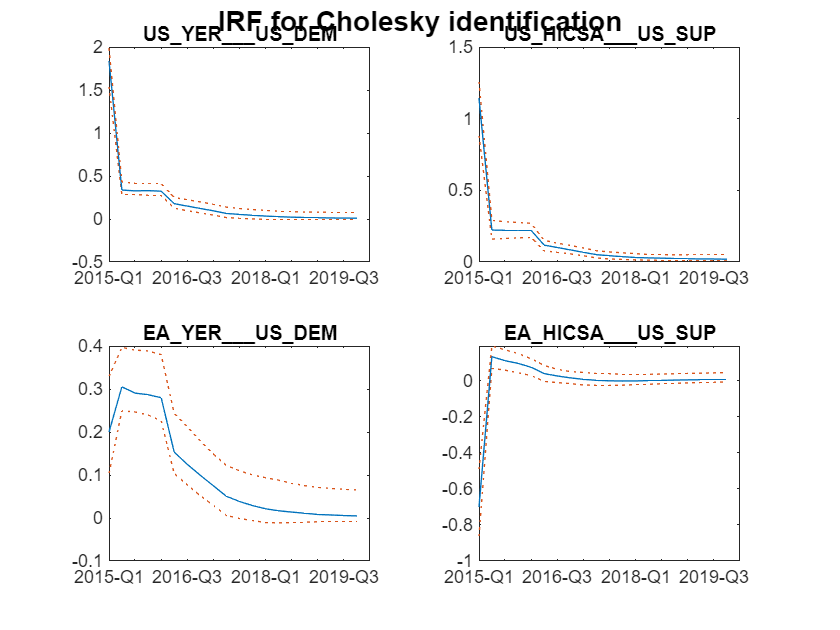




ch = visual.Chartpack( ...
  span=plotSpan, ...
  namesToPlot=["US_YER___US_DEM","US_HICSA___US_SUP","EA_YER___US_DEM", "EA_HICSA___US_SUP" ], ...
  plotSettings=plotSettings ...
);

ch.Captions = "IRF for Cholesky identification";
ch.plot(respTbl1);